# **OFDM Receiver Using Software Defined Radio**

## Set OFDM Frame Parameters

Set the OFDM parameters, including the FFT length, cyclic prefix length, and number of subcarriers. The pilot subcarrier spacing and channel bandwidth are fixed at 30 KHz and 3 MHz, respectively.

After configuring the OFDM parameters, set the data parameters. Set the modulation order, code rate, number of symbols per frame, and the number of frames per transmission. 

You can enable or disable the scopes for visualization, however for long simulations, it is recommended to disable the scope. To control the display of the diagnostic output text, enable or disable the verbosity as needed. To view the decoded data in each frame, enable the print data flag

% The chosen set of OFDM parameters:
OFDMParams.FFTLength              = 128;   % FFT length
OFDMParams.CPLength               = 32;    % Cyclic prefix length
OFDMParams.NumSubcarriers         = 72;    % Number of sub-carriers in the band
OFDMParams.Subcarrierspacing      = 3e3;  % Sub-carrier spacing of 30 KHz
OFDMParams.PilotSubcarrierSpacing = 9;     % Pilot sub-carrier spacing
OFDMParams.channelBW              = 3e5;   % Bandwidth of the channel 3 MHz

% Data Parameters
dataParams.modOrder       = 256;   % Data modulation order
dataParams.coderate       = "3/4";   % Code rate
dataParams.numSymPerFrame = 25;   % Number of data symbols per frame
dataParams.numFrames      = 25;   % Number of frames to transmit
dataParams.enableScopes   = true;                    % Switch to enable or disable the visibility of scopes
dataParams.verbosity      = true;                    % Control to print the output diagnostics at each level of receiver processing
dataParams.printData      = true;                    % Control to print the output decoded data

## Initialize Receiver Parameters

The `helperGetRadioParams` function initializes the receiver System object™  `ofdmRx.` Assign the name of the radio you are using for receiving the OFDM signal to the variable `radioDevice`. Set the receiver gain and operating center frequency.

The `helperGetRadioRxObj` function initializes the radio receiver System object.

radioDevice            = "PLUTO";   % Choose radio device for reception
centerFrequency        = 865e6;   % Center Frequency
gain                   = 40;   % Set radio gain

The `helperOFDMSetParamsSDR` function initializes transmit-specific and common transmitter and receiver parameters required for the OFDM simulation and the `helperGetRadioParams` function initializes the paramters required for the receiver System object™ radio.

[sysParam,txParam,transportBlk] = helperOFDMSetParamsSDR(OFDMParams,dataParams);
sampleRate                       = sysParam.scs*sysParam.FFTLen;                % Sample rate of signal

ofdmRx = helperGetRadioParams(sysParam,radioDevice,sampleRate,centerFrequency,gain);
[radio,spectrumAnalyze,constDiag] = helperGetRadioRxObj(ofdmRx);

## Execute Receiver Loop

#### Synchronization

The OFDM receiver checks the sample buffer for the synchronization symbol to find the starting point of the data frames within the received OFDM signal. The receiver correlated the received OFDM signal with the known synchronization symbol. Once the OFDM receiver detects a high correlation peak, it identifies the position where it finds the synchronization symbol as the start of the frame  

#### Frequency Offset Estimation and Correction

The OFDM receiver estimates and corrects the frequency and timing offset introduced to the transmitted OFDM signal due to channel impairments. The OFDM receiver checks the receiver buffer for the required number of frames and performs automatic frequency correction over each symbol. The receiver averages the frequency correction across the subcarriers and then across every six symbols, considering a group of six symbols as a slot. The receiver considers the overall average value of these corrections as the frequency offset and compensates this frequency offset across the entire frame.

The receiver is considered camped to a based station upon achieving successful synchronization and channel impairment correction. 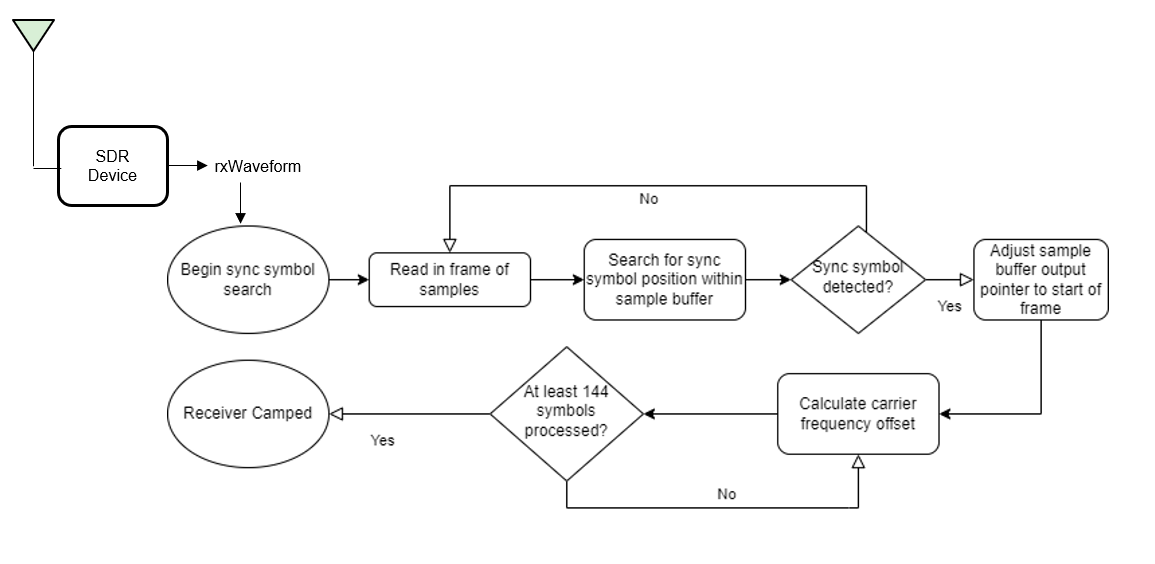

### Receiver Processing

This process is the reverse of the process that happens at the transmitter.

#### Channel Estimation and Equalization

Initially, the OFDM receiver performs channel estimation on the OFDM demodulated reference symbols. To remove the effects of time-varying fading, the receiver selects two reference symbols from adjacent frames to estimate the channel at two different points in time. The receiver then linearly interpolates the channel estimates between the two reference symbols to get the channel estimates for the header and data symbols. The `ofdmEqualize` function then equalizes the reference symbols and data symbols using the channel estimates.

#### Header Decoding

The receiver extracts and decodes the header symbols to get the data symbol parameters such as FFT length, subcarrier modulation scheme, and code rate. The receiver uses these parameters to demodulate and decode the data symbols.

#### Data Decoding

The common phase error (CPE) affects all subcarriers equally and the OFDM receiver uses the pilot symbols within the data symbols to estimate CPE. The `helperOFDMRx` function corrects the phase errors in the data symbols and the `qamdemod` function soft decodes the data subcarriers into log likelihood ratios (LLRs).

The receiver then deinterleaves the demodulated bitstream and the `vitdec` function performs maximum likelihood decoding using the Viterbi algorithm. The descrambler descrambles the decoded bits, and the `comm.CRCDetector` computes the cyclic redundancy check (CRC) and compares it with the appended CRC.

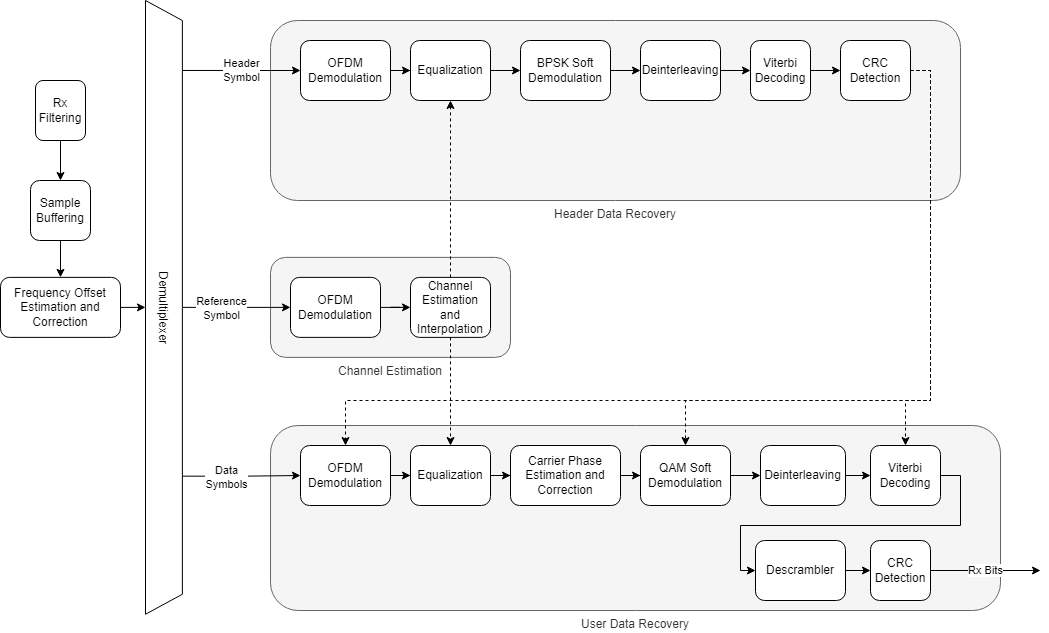

## Establishing connection to hardware. This process can take several seconds.


........................

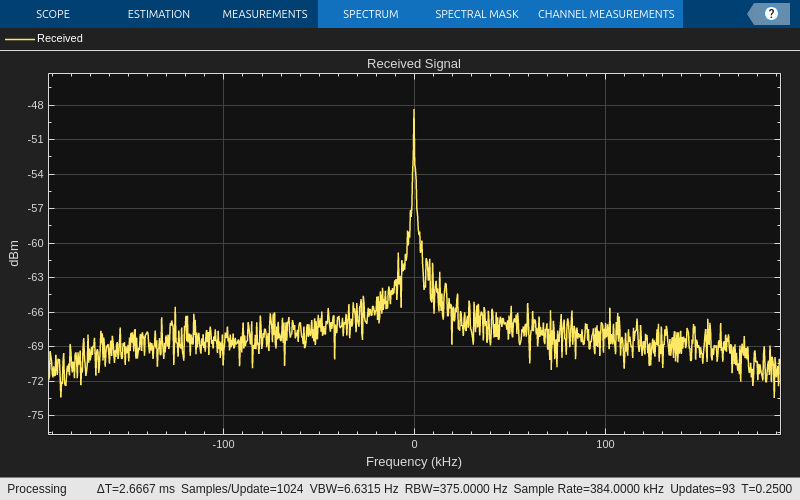

% Clear all the function data as they contain some persistent variables
clear helperOFDMRx helperOFDMRxFrontEnd helperOFDMRxSearch helperOFDMFrequencyOffset;
close all;

errorRate = comm.ErrorRate();
toverflow = 0; % Receiver overflow count
rxObj = helperOFDMRxInit(sysParam);
BER = zeros(1,dataParams.numFrames);
for frameNum = 1:dataParams.numFrames
    sysParam.frameNum = frameNum;
    [rxWaveform, ~, overflow] = radio();

    toverflow = toverflow + overflow;

    % Run the receiver front-end only when there is no overflow
    if ~overflow
        rxIn = helperOFDMRxFrontEnd(rxWaveform,sysParam,rxObj);

        % Run the receiver processing
        [rxDataBits,isConnected,toff,rxDiagnostics] = helperOFDMRx(rxIn,sysParam,rxObj);
        sysParam.timingAdvance = toff;

        % Collect bit and frame error statistics
        if isConnected
            % Continuously update the bit error rate using the |comm.ErrorRate|
            % System object
            berVals = errorRate(...
                transportBlk((1:sysParam.trBlkSize)).', ...
                rxDataBits);
            BER(frameNum) = berVals(1);
            if dataParams.printData
                % As each character in the data is encoded by 7 bits, decode the received data up to last multiples of 7
                numBitsToDecode = length(rxDataBits) - mod(length(rxDataBits),7);
                recData = char(bit2int(reshape(rxDataBits(1:numBitsToDecode),7,[]),7));
                fprintf('Received data in frame %d: %s',frameNum,recData);
            end
        end

        if isConnected && dataParams.enableScopes
            constDiag(complex(rxDiagnostics.rxConstellationHeader(:)), ...
                 complex(rxDiagnostics.rxConstellationData(:)));
        end

        if dataParams.enableScopes
            spectrumAnalyze(rxWaveform);
        end
    end
end

% Display the mean BER value across all frames
fprintf('Simulation complete!\nAverage BER = %d',mean(BER))

Simulation complete!
Average BER = 0


release(radio);

## Troubleshooting

#### **No data in any frame**

Problem

- The receiver continuously receives no data in any frame.

Possible causes

- Transmitter is not running

- Too high or too low transmitter and receiver gains

- Too many under-runs at the transmitter

Possible solutions

- Ensure that the transmitter is running

- Adjust the transmitter and receiver gains

- Adjust the frame length to make sure there are very few under-runs at the transmitter.

#### **Header CRC fails**

Problem

- Even when synchronization and receiver camping are successful, the header CRC check fails.

Possible causes

-  Insufficient compensation of clock frequency offset.

Possible solutions

- The frequency compensation algorithm measures and corrects the frequency and phase offset for each frame, and it can estimate the correct offset up to half of the subcarrier spacing. You can calibrate the frequency offset to resolve this error.

For USRP radios, you can determine the frequency offset by sending a tone at a known frequency from the transmitter and measure the offset between the transmitted and received frequency. Apply the measured offset to the center frequency of `comm.SDRuReceiver` receiver System object.

For ADALM-Pluto radios, run the [Frequency offset calibration with ADALM-Pluto Radio in Simulink](docid:plutoradio_ug#mw_baa863fb-d239-4495-baf9-eb6864e0f592) example to get the frequency offset. Apply the measured offset to the center frequency of the `comm.SDRRxPluto`  receiver System object.

#### **Data decoding fails**

Problem

- The data decoding fails even when the header CRC decoding is successful.

Possible causes

- Data overflow at the receiver

- Inaccurate channel estimate due to exceeding frame length.

Possible solutions

-  Adjust the frame size

- Change the number of symbols per frame to minimize the frame length.

## Further Exploration

You can use an external clock source or GPSDO with the radios to try smaller subcarrier spacing of 15 KHz with smaller bandwidths such as 1.4 MHz (LTE bandwidths) or higher FFTLengths such as 256. 

This example uses burst mode in the radios to receive the data, with the burst size set to the number of frames. You can further explore receiving the data using the radios in non-burst mode.

*Copyright 2023-2024 The MathWorks, Inc.*